# **Sesion 2.1.-DETERMINACIÓN DE LA MATRIZ DE TRANSFORMACIÓN HOMOGÉNEA UTILIZANDO DENAVIT-HARTENBERG **

- Objetivo: Encontrar una matriz de transformación homogénea T que relacione la posición y orientación del extremo del robot con respecto a un sistema de referencia fijo situado en su base

- Matriz ${}^{i-1}A_i$: matriz de transforación homogénea que representa la posición y orientación relativa entre los sistemas asociados a dos eslabones consecutivos del robot

- Matriz T: matriz ${}^0A_n$ cuando se consideran todos los grados de libertad del robot

    
$$T=^0 A_n =$$

$${}^0A_1\;\;{}^1A_2\;\;{}^2A_3\ldotp \ldotp \ldotp {}^{n-1}A_n$$


- Denavit-Hartenberg propusieron en 1955 un método matricial que permite establecer de manera sistemática un sistema de coordenadas (*Si*) ligado a cada eslabón *i *de una cadena articulada, pudiéndose determinar a partir de él, el modelo cinemático del robot.

- Según la representación D-H, escogiendo adecuadamente los sistemas de coordenadas asociados para cada eslabón, será posible pasar de un sistema de coordenadas al siguiente, mediante **4 transformaciones básicas **que dependen exclusivamente de las características geométricas del eslabón.

- Estas transformaciones básicas consisten en una sucesión de rotaciones y traslaciones que permitan relacionar el sistema de coordenadas del eslabón *i *con el eslabón *i-1*  

- Transformaciones básicas de paso de eslabón (definidas sobre sistema móvil -> postmultiplicar): 

                    – Rotación alrededor del eje $z_{i-1}$ un ángulo θi

                    – Traslación a lo largo de zi una distancia di ; vector di (0,0,di)

                    – Traslación a lo largo de xi una distancia ai ; vector ai (0,0,ai)

                    – Rotación alrededor del eje x i un ángulo ai  

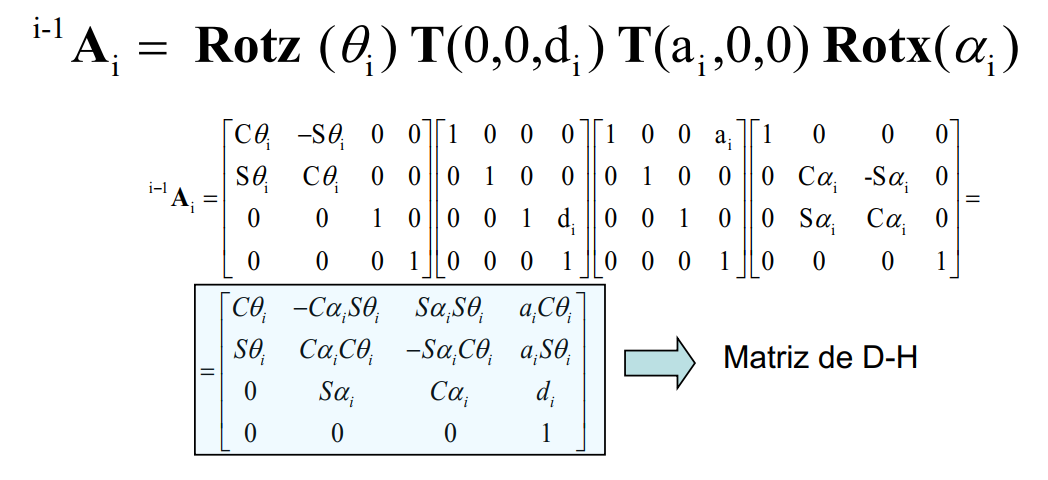

**Ejemplo para un robot planar de 2gdl. Parámetros geométricos del robot son : a1 = 20; a2 = 10; theta1 =0; theta2= pi/2;**

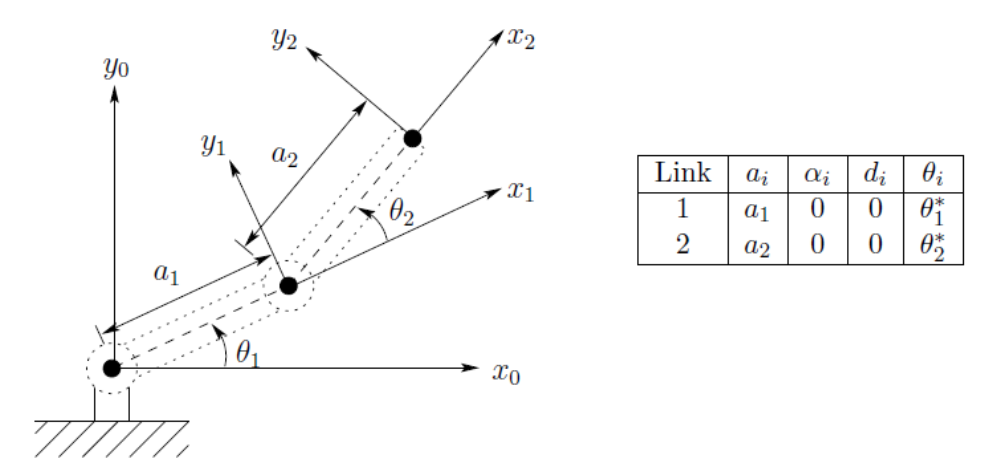

## Determinación mediante la definición de la matriz DH de manera simbólica

El comando [syms](https://es.mathworks.com/help/symbolic/syms.html?searchHighlight=syms&s_tid=srchtitle_syms_1) de Matlab permite crear variables simbólicas.Vamos a determinar la matriz de transformación homogénea de manera simbólica, a partir de su definición.

Definimos los parámetros del robot:

clear
syms a1 a2 theta1 theta2
alphaa = [0,0]; % this is the alpha value for all  the link
a=[a1, a2]; % Length of the Link
d=[0,0]; %Offset
thethaa=[theta1,theta2]; % joint angle variation

%Comprobamos la dimensionalidad de los vectores alphaa, a, d y thethaa
n = length(thethaa);
assert((length(alphaa)==n) && (length(a)==n) && (length(d)==n), ...
    'Los vectores no tienen la misma dimensión')

Calculo de las matrices de transformación homogénea ${}^{i-1}A_i$que representa la posición y orientación relativa entre los sistemas asociados a dos eslabones consecutivos del robot. La matriz ${}^{i-1}A_i$ se define como:

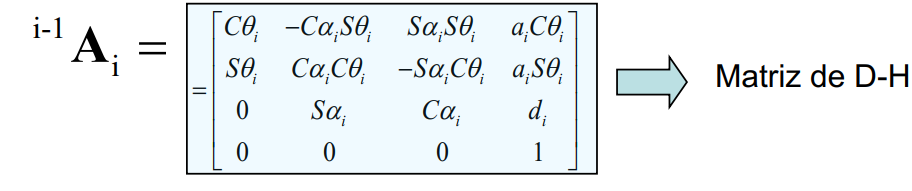

for i = 1:n
     MTH.(sprintf('A%d%d', i-1,i))= ...
        [cos(thethaa(i)),-cos(alphaa(i))*sin(thethaa(i)),sin(alphaa(i))*sin(thethaa(i)),a(i)*cos(thethaa(i));...
        sin(thethaa(i)),cos(alphaa(i))*cos(thethaa(i)),-sin(alphaa(i))*cos(thethaa(i)),a(i)*sin(thethaa(i));...
        0,sin(alphaa(i)),cos(alphaa(i)),d(i);...
        0,0,0,1];
end

Mostramos los resultados por pantalla

for i = 1:n
     disp (sprintf('A%d%d = ', i-1,i))
     disp (MTH.(sprintf('A%d%d', i-1,i)))
end

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Calculamos la matriz de transformación homogénea final (T) aquella que relaciona el sistema de coordenadas d ela base del robot, con el sistema de coordenadas del extremo del robot.

T = eye (4);
for i=1:n
    T= T*MTH.(sprintf('A%d%d', i-1,i));
end
simplify (T)

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Con la función [subs](https://es.mathworks.com/help/symbolic/subs.html), se puede evaluar el valor de la solución obtenida. 

Introducimos los parámetros del sistema a1 = 20; a2 = 10; theta1 = 0; theta2 = 90º

a1 = 20;
a2 = 10;
theta1 =0;
theta2= pi/2;


subs (MTH.A01)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 20\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

subs (MTH.A12)

$$ans = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 1 & 0 & 0 & 10\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

subs(T)

$$ans = \left(\begin{array}{cccc} 0 & -1 & 0 & 20\\ 1 & 0 & 0 & 10\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Determinación mediante la multiplicación de las 4 transformaciones básicas**

Otra manera de calcular una matriz de transformación homogénea es mediante la multiplicación de 4 transformaciones básicas.

La función [makehgtform](https://es.mathworks.com/help/matlab/ref/makehgtform.html?searchHighlight=makehgtform&s_tid=srchtitle_makehgtform_1) crea una matriz de transformación homogénea 4x4 de transformación, escalado o rotación. La expresión genérica para calcualr una matriz de transformación homogénea mediante la multiplicación de 4 transformaciones utilizando la función makehgtform es la siguiente:

Calculamos las matrices de transformación homogénea del robot planar anterior. Observamos como el resultado es el mismo.

A01 = makehgtform('zrotate',0) * makehgtform('translate',[a1 0 0])

A01 =      1     0     0    20
     0     1     0     0
     0     0     1     0
     0     0     0     1


A12 = makehgtform('zrotate',theta2) * makehgtform('translate',[a2 0 0])

A12 =      0    -1     0     0
     1     0     0    10
     0     0     1     0
     0     0     0     1


T = A01 *A12

T =      0    -1     0    20
     1     0     0    10
     0     0     1     0
     0     0     0     1
